# Light curvesと姿勢をplotしたい

clc
clear
close all
addpath('../../hara_functions/')


変えるところ

type = 2; % 1:lightcurves, 2:attitude
filenumber = '002'

filenumber = '002'

curdir = pwd;
datadir = strcat(curdir, '/../train_data_using_yoshimulibrary/')

datadir = '/Users/hararyui/Documents/lc_gpr/gpr/confirmation/../train_data_using_yoshimulibrary/'

% lightcurves
filename = strcat('t_mApp_boxWing', filenumber, '.csv');
datapath = strcat(datadir, filename)

datapath = '/Users/hararyui/Documents/lc_gpr/gpr/confirmation/../train_data_using_yoshimulibrary/t_mApp_boxWing002.csv'

t_mApp = readmatrix(datapath);
% attitude
filename = strcat('X_boxWing', filenumber, '.csv');
datapath = strcat(datadir, filename)

datapath = '/Users/hararyui/Documents/lc_gpr/gpr/confirmation/../train_data_using_yoshimulibrary/X_boxWing002.csv'

X = readmatrix(datapath);
X = [q2zyx_h(X(:,1:4)), X(:,5:7)];

savedir = strcat(curdir, '/../../../temporary/');

plot

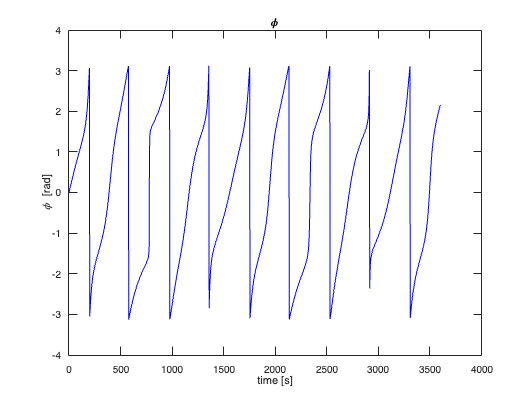

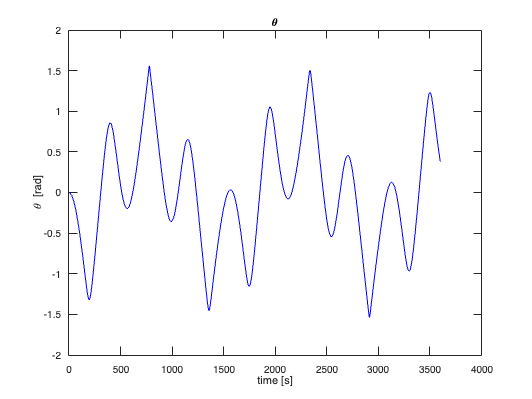

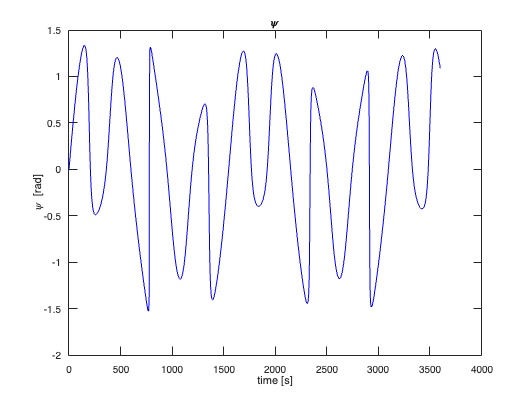

if type == 1
    f = figure("Name", 'LightCurves');
    plot(t_mApp(:,1), t_mApp(:,2), 'b-');
    xlabel('time [s]');
    ylabel('magnitude');
    title('Light curves');
    exportgraphics(gcf, strcat(savedir, 'lightcurves.pdf'));
elseif type == 2
    f = figure("Name", 'phi');
    plot(t_mApp(:,1), X(:,1), 'b-');
    xlabel('time [s]');
    ylabel('\phi [rad]');
    title('\phi');
    exportgraphics(gcf, strcat(savedir, 'phi.pdf'));

    f = figure("Name", 'theta');
    plot(t_mApp(:,1), X(:,2), 'b-');
    xlabel('time [s]');
    ylabel('\theta [rad]');
    title('\theta');
    exportgraphics(gcf, strcat(savedir, 'theta.pdf'));

    f = figure("Name", 'psi');
    plot(t_mApp(:,1), X(:,3), 'b-');
    xlabel('time [s]');
    ylabel('\psi [rad]');
    title('\psi');
    exportgraphics(gcf, strcat(savedir, 'psi.pdf'));
end